## PID Constant Setpoint Error

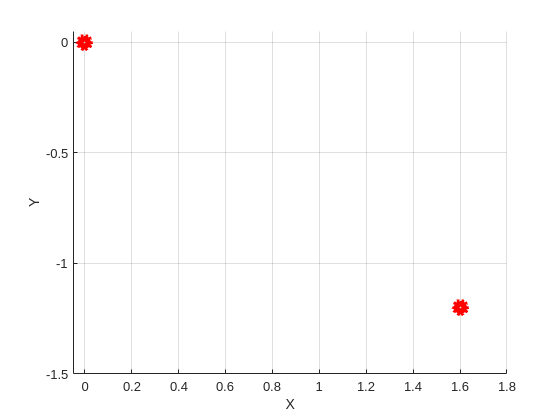

Error using rectangle
Value must be a 4 element vector

Error in parser>@(minx,maxx,miny,maxy)rectangle('Position',[minx,miny,(maxx-minx),(maxy-miny)],'LineWidth',3) (line 44)
rectplot = @(minx, maxx, miny, maxy) rectangle('Position',[minx miny (maxx-minx) (maxy-miny)], 'LineWidth',3);

files = dir('PID_Run*.csv');
N = length(files);

info = [];
figure;
xlim([-0.05 1.8])
ylim([-1.5 0.05])
hold on;
plot([0,1.6],[0,-1.2],'rp','linewidth',10, 'HandleVisibility','off');
grid on;
xlabel('X');
ylabel('Y');
endx = [];
endy = [];
for i = 1:2:N
    % if i==5
    %     continue;
    % end
    title(strcat('Run', num2str(i)));
    h = animatedline('LineWidth',2, 'HandleVisibility','off');
    info = table2array(readtable(files(i).name));
    idx = find(info(:,10)==-10,1);
    if isempty(idx)
        idx = length(info);
    end
    info = info(1:idx,:);
    for j = 1:2:length(info)
        addpoints(h,info(j,2), info(j,3));
        drawnow;
    end
    plot(info(:,2), info(:,3), 'DisplayName',strcat('Run', num2str(i)));
    endx = [endx,info(end,2)];
    endy = [endy,info(end,3)];
    plot(endx(end), endy(end), '*', 'linewidth',3,'HandleVisibility','off');
    clearpoints(h);
    

end
minx = min(endx);
maxx = max(endx);
miny = min(endy);
maxy = max(endy);
rectplot = @(minx, maxx, miny, maxy) rectangle('Position',[minx miny (maxx-minx) (maxy-miny)], 'LineWidth',3);
rectplot(minx, maxx,miny, maxy);

hold off;
legend;

## PID Circular Setpoint

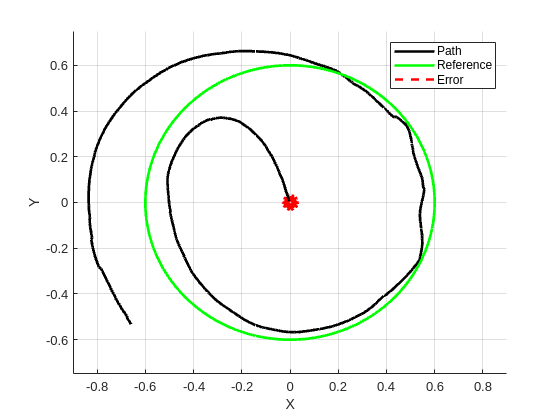

file = dir('PID_circle.csv');

info = [];
figure;
xlim([-0.9 0.9])
ylim([-0.75 0.75])
hold on;
plot([0,1.6],[0,-1.2],'rp','linewidth',10, 'HandleVisibility','off');
grid on;
xlabel('X');
ylabel('Y');
endx = [];
endy = [];
h = animatedline('LineWidth',2, 'DisplayName','Path');
g = animatedline('LineWidth',2,'Linestyle','-','Color','g', 'DisplayName','Reference');
k = animatedline('LineWidth',2,'Linestyle','--','Color','r', 'DisplayName','Error');
info = table2array(readtable(file.name));
idx = find(info(:,10)==-10,1);
x = 0.6*cos(0.1*pi*[info(1,1):0.01:info(1,1)+30]);
y = 0.6*sin(0.1*pi*[info(1,1):0.01:info(1,1)+30]);
if isempty(idx)
    idx = length(info);
end
info = info(1:idx,:);

for j = 1:4:length(info)
    addpoints(h,info(j,2), info(j,3));
    addpoints(g,x(j), y(j));
    addpoints(k,[info(j,2) x(j)], [info(j,3) y(j)]);
    tx = text(-0.2,-0.2,strcat('Distance : ',num2str(sqrt((info(j,2)-x(j))^2 + (info(j,3)-y(j))^2)),'m'));
    drawnow;
    delete(tx)
    clearpoints(k);
end
hold off;
legend;

## MPC Error

files = dir('MPC_Run*.csv');
N = length(files);

info = [];
figure;
xlim([-0.05 1.7])
ylim([-1.4 0.05])
hold on;
plot([0,1.6],[0,-1.2],'rp','linewidth',10, 'HandleVisibility','off');
grid on;
xlabel('X');
ylabel('Y');
endx = [];
endy = [];
for i = 1:N
    % if i==5
    %     continue;
    % end
    title(strcat('Run', num2str(i)));
    h = animatedline('LineWidth',2, 'HandleVisibility','off');
    info = table2array(readtable(files(i).name));
    idx = find(info(:,16)==-10,1);
    if isempty(idx)
        idx = length(info);
    end
    info = info(1:idx,:);
    for j = 1:length(info)
        addpoints(h,info(j,2), info(j,3));
        drawnow;
    end
    plot(info(:,2), info(:,3), 'DisplayName',strcat('Run', num2str(i)));
    endx(i) = info(end,2);
    endy(i) = info(end,3);
    plot(endx(end), endy(end), '*', 'linewidth',3,'HandleVisibility','off');
    clearpoints(h);

end
minx = min(endx);
maxx = max(endx);
miny = min(endy);
maxy = max(endy);
rectplot = @(minx, maxx, miny, maxy) rectangle('Position',[minx miny (maxx-minx) (maxy-miny)], 'LineWidth',3);
rectplot(minx, maxx,miny, maxy);
hold off;
legend;

## MPC Circle

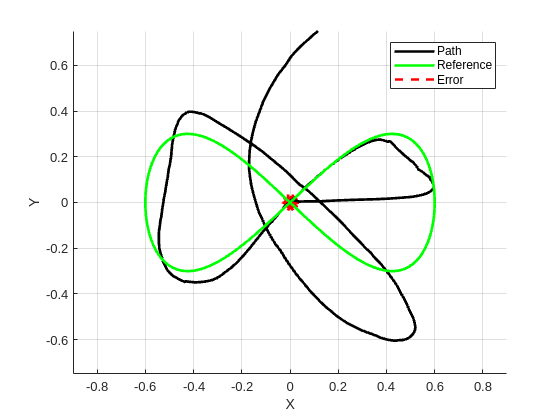

file = dir('MPC_lem5.csv');

info = [];
figure;
xlim([-0.9 0.9])
ylim([-0.75 0.75])
hold on;
plot([0,1.6],[0,-1.2],'rp','linewidth',10, 'HandleVisibility','off');
grid on;
xlabel('X');
ylabel('Y');
endx = [];
endy = [];
h = animatedline('LineWidth',2, 'DisplayName','Path');
g = animatedline('LineWidth',2,'Linestyle','-','Color','g', 'DisplayName','Reference');
k = animatedline('LineWidth',2,'Linestyle','--','Color','r', 'DisplayName','Error');
info = table2array(readtable(file.name));
idx = find(info(:,16)==-10,1);
% x = 0.6*cos(0.1*pi*[info(1,1):0.01:info(1,1)+30]);
% y = 0.6*sin(0.1*pi*[info(1,1):0.01:info(1,1)+30]);
if isempty(idx)
    idx = length(info);
end
info = info(1:idx,:);

for j = 1:4:length(info)
    addpoints(h,info(j,2), info(j,3));
    addpoints(g,info(j,11), info(j,12));
    addpoints(k,[info(j,2) info(j,11)], [info(j,3) info(j,12)]);
    tx = text(-0.2,-0.2,strcat('Distance : ',num2str(sqrt((info(j,2)-info(j,11))^2 + (info(j,3)-info(j,12))^2)),'m'));
    drawnow;
    if j<length(info)-2
        delete(tx)
    end
    clearpoints(k);
end
hold off;
legend;

## Vy Time Constant Identification

files = dir('Vy*.csv');
N = length(files);

info = [];
figure;
xline(0,'LineWidth',3,'HandleVisibility','off');
yline(0, 'LineWidth',3, 'HandleVisibility','off');
hold on;
tc = [];
c = ['r', 'b', 'g', 'c', 'k','m'];
for i = 1:N
    info = table2array(readtable(files(i).name));
    id1 = find(info(:,6)>0,1);
    info = info(id1:end,:);
    info(:,1) = info(:,1) - info(1,1);
    plot(info(:,1), info(:,6), c(i), 'LineWidth',1, 'DisplayName',strcat('Run',num2str(i)));
    
    id2 = find(info(:,6)>0.63,1);
    tc(i) = interp1([info(id2-1,6),info(id2,6)],[info(id2-1,1),info(id2,1)],0.63);
    plot(tc(i), 0.63,strcat(c(i),'o'), 'linewidth',4, 'HandleVisibility','off');
    plot([tc(i) tc(i)],[0 0.63], strcat(c(i), '--'), 'HandleVisibility','off');
    plot([0 tc(i)],[0.63 0.63], strcat(c(i), '--'), 'HandleVisibility','off');
end
ylim([0 1]);
grid on;
xlabel('Time (s)');
ylabel('Global Y-Velocity');
title('V_y World Velocity Response');
hold off;
legend;
tau_y = mean(tc)

## Vx Time Constant Identification

files = dir('Vx*.csv');
N = length(files);

info = [];
figure;
xline(0,'LineWidth',3,'HandleVisibility','off');
yline(0, 'LineWidth',3, 'HandleVisibility','off');
hold on;
tc = [];
c = ['r', 'b', 'g', 'c', 'k','m'];
for i = 1:N
    info = table2array(readtable(files(i).name));
    id1 = find(info(:,5)>0,1);
    info = info(id1:end,:);
    info(:,1) = info(:,1) - info(1,1);
    plot(info(:,1), info(:,5), c(i), 'LineWidth',1, 'DisplayName',strcat('Run',num2str(i)));
    
    id2 = find(info(:,5)>0.63,1);
    tc(i) = interp1([info(id2-1,5),info(id2,5)],[info(id2-1,1),info(id2,1)],0.63);
    plot(tc(i), 0.63,strcat(c(i),'o'), 'linewidth',4, 'HandleVisibility','off');
    plot([tc(i) tc(i)],[0 0.63], strcat(c(i), '--'), 'HandleVisibility','off');
    plot([0 tc(i)],[0.63 0.63], strcat(c(i), '--'), 'HandleVisibility','off');
end
ylim([0 1]);
grid on;
xlabel('Time (s)');
ylabel('Global X-Velocity');
title('V_x World Velocity Response');
xticks([0:0.2:2.5]);
hold off;
legend;
tau_x = mean(tc)

## Vz Response Identification

files = dir('Vz*.csv');
N = length(files);

info = [];
figure;
xline(0,'LineWidth',3,'HandleVisibility','off');
yline(0, 'LineWidth',3, 'HandleVisibility','off');
hold on;
tc = [];
ssv = [];
c = ['r', 'b', 'g', 'c', 'k','m'];
for i = 1:N
    info = table2array(readtable(files(i).name));
    ssv = 0.5418;
    tcv = 0.632*ssv;
    info(:,1) = info(:,1) - info(1,1);
    plot(info(:,1), info(:,7), c(i), 'LineWidth',1, 'DisplayName',strcat('Run',num2str(i)));
    
    id2 = find(info(:,7)>tcv,1);
    tc(i) = interp1([info(id2-1,7),info(id2,7)],[info(id2-1,1),info(id2,1)],tcv);
    plot(tc(i), tcv,strcat(c(i),'o'), 'linewidth',4, 'HandleVisibility','off');
    plot([tc(i) tc(i)],[0 tcv], strcat(c(i), '--'), 'HandleVisibility','off');
    plot([0 tc(i)],[tcv tcv], strcat(c(i), '--'), 'HandleVisibility','off');
end
ylim([0 1]);
grid on;
xlabel('Time (s)');
ylabel('Global Z-Velocity');
title('V_z World Velocity Response');
xticks([0:0.2:2.5]);
hold off;
legend;
tau_z = mean(tc)